# Plots for Final Project

## Data processing

% import excel file with zscore data
data_directory = 'C:\Users\lizan\Desktop\Classes\ICM Imaging\ICM_ImagingFinalProject_Group6\Data\';
ADNI_filename = 'ADNI_zscores.xlsx';
path = fullfile(data_directory, ADNI_filename);

% read the table
MNI_zscores_table = readtable(path);
MNI_zscores_table = MNI_zscores_table(:,2:end);

% convert table values to array
ADNI_zscores_array = table2array(MNI_zscores_table(:,2:end));

## Plot 1: Heatmap of Barcodes of All Patients from ADNI Dataset

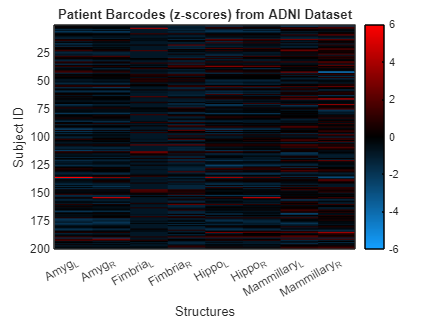

% specify x and y values
xvalues = MNI_zscores_table.Properties.VariableNames(2:end);
yvalues = MNI_zscores_table{:,1};

% create heatmap
h = heatmap(xvalues, yvalues, ADNI_zscores_array);

% modify ylabels
ylabels = string(yvalues);
ylabels(mod(1:200,25) ~= 0) = " ";
h.YDisplayLabels = ylabels;

% Add labels 
h.Title = 'Patient Barcodes (z-scores) from ADNI Dataset';
h.XLabel = 'Structures';
h.YLabel = 'Subject ID';

% turn the grid off
grid off

% set the colormap
h.Colormap = CustomColormap;
h.ColorLimits = [-6 6];

## Plot 2: Heatmap of Barcodes of Subset of 15 Patients from ADNI Dataset

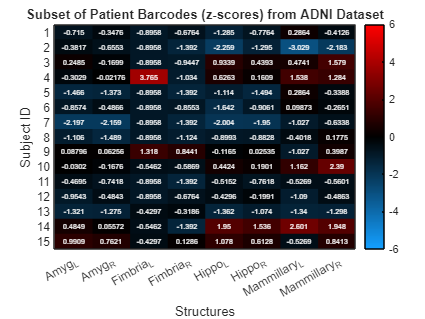

h = heatmap(xvalues, yvalues(1:15), ADNI_zscores_array(1:15,:));
% Add labels 
h.Title = 'Subset of Patient Barcodes (z-scores) from ADNI Dataset';
h.XLabel = 'Structures';
h.YLabel = 'Subject ID';

% turn the grid off
grid off

% set the colormap
h.Colormap = CustomColormap;
h.ColorLimits = [-6 6];

## Plot 3: Barcode Heatmap of MNI Atlas Dataset

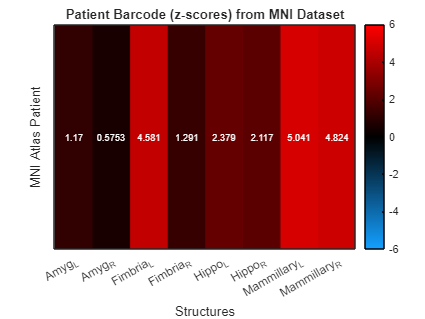

% import excel file with zscore data
MNI_filename = 'MNI_zscores.xlsx';
path = fullfile(data_directory, MNI_filename);

% read the table
MNI_zscores_table = readtable(path);

% convert table values to array
MNI_zscores_array = table2array(MNI_zscores_table(:,2:end));

% specify x and y values
xvalues = MNI_zscores_table.Properties.VariableNames(2:end);
yvalues = {'0'};
ylabels = {' '};

% create heatmap
h = heatmap(xvalues, yvalues, MNI_zscores_array);

% Add labels 
h.Title = 'Patient Barcode (z-scores) from MNI Dataset';
h.XLabel = 'Structures';
h.YLabel = 'MNI Atlas Patient';

% turn the grid off
grid off

% set the colormap
h.Colormap = CustomColormap;
h.ColorLimits = [-6 6];
h.YDisplayLabels = ylabels;